# Sessió 10

## 1. App Classification Learner

L’objectiu d’aquesta pràctica és aprendre a classificar mostresa partir dels seus vectors de caracterìstiques. Usarem la App Classification learner de Matlab. Trobareu la informació necessària a:

https://uk.mathworks.com/help/stats/train-decision-trees-in-classification-learner-app.html

https://uk.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html

Podeu utilitzar el dataset Fisher iris (tot un clàssic) i experimentar amb diferents classificadors. En acabar heu de ser capaços de:

- Tunnejar correctament els paràmetres d’un classificador

- Probar diferents classificadors i escollir-ne els que donin millors resultats

- Fer experiments amb rigor (p.ex: cross-validation)

- Presentar els resultats de forma correcta ( corba RoC, matriu de confusió...)

fishertable = readtable('fisheriris.csv');
view(trainedModel.ClassificationTree,'Mode','graph');
yfit = trainedModel.predictFcn(fishertable);


## 2. Classificació automàtica d’espècies arbòries

Un cop domineu la app Clasification learner, es planteja un problema de classificació amb imatges reals. Dins la tasca corresponent a la sessió 10 a Atenea, trobareu imatges de fulles de roure, faig i plàtan. Entreneu varios classificadors per aquestes tres espècies usant com a vectors de característiques els seus descriptors de Fourier. Es demana un informe (en pdf) que inclogui el codi usat per a obtenir els descriptors, la descripció dels experiments realitzats, els classificadors que han funcionat millor i els resultats obtinguts. Indiqueu quines caracaterístiques del vector són necessàries per a la correcta classificació, i quines no són significatives.

Al trabajar con los descriptores de Fourier de las respectivas imagenes, se nos planteó el dilema de usar el modulo de los descriptores odividir los descriptores, que son números complejos, en dos partes, real e imaginaria.

Haremos pruebas de ambos casos y decidiremos cual nos dá un mejor resultado.

## Clasificación 

Primero estudiaremos los resultado en función del número de descriptores (5, 10 , 50 ,100, 1000)

Para las pruebas, hemos decidido dividir nuestros datos en 2 conjuntos: Train y Test.

Test es un 30% del total de los datos y serán escogidos aleatoriamente en cada prueba, sin embargo, sabremos que del 30%, el primer tercio son Arce, el segundo tercio son Haya y el último tercio son Roble.

### Clasificación usando parte real e imaginaria

- Usando 5 descriptores nos da los siguientes resultados:

            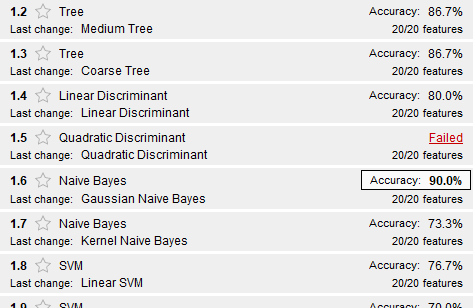

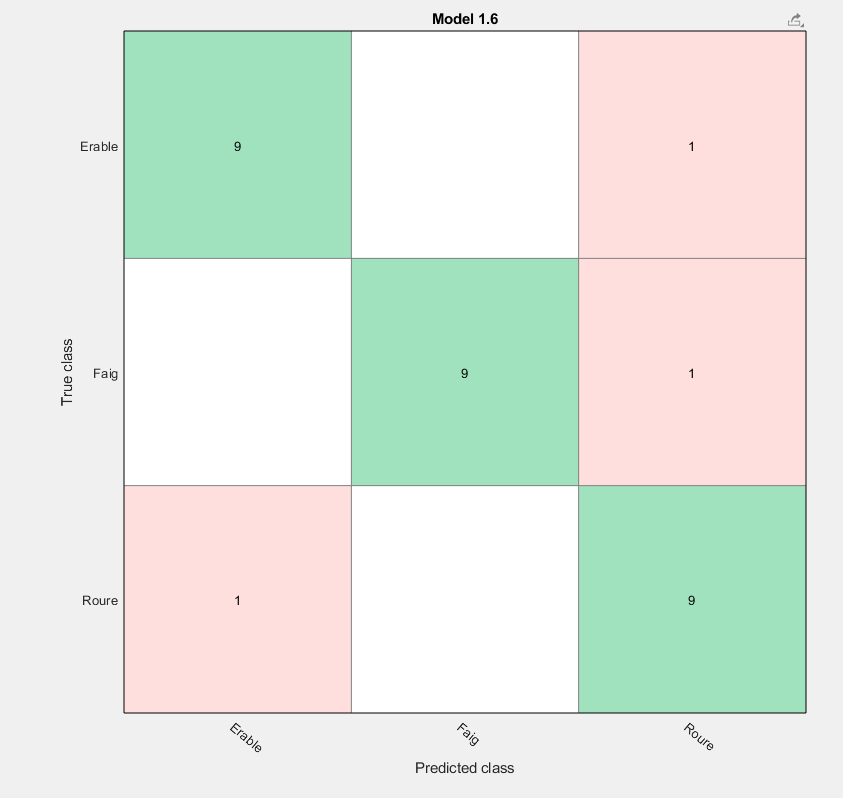

Haremos una prueba con los datos Test:

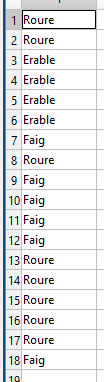

Como se puede observar y sabiendo los resultados correctos expuestos arriba, hay un gran porcentaje de fallos, un 20% aproximadamente. 

- Usando 20 descriptores nos da los siguientes resultados:

### Clasificación usando el módulo

- Usando 5 descriptores nos da los siguientes resultados:

%im = imread('l2nr002.jpg')
%[descriptor] = descriptor_fourier(im,nan)
p = randperm(16);
train = p(1:10);
test = p(11:16);
[T1Train, T2Train, dataTrain] = getdataexercise2(train)

data =   -27.6601    6.7120    7.0322    7.0347    7.1219    6.4209    5.7175    7.2545    7.3716    9.6289
    4.2374    7.9803    7.6499    5.5623    7.1377    7.2549    7.7136    7.4261    7.2272   10.2555
  -26.5127    9.9683    9.6453    8.8969    7.4996    5.9646    8.7158    8.8624    8.7375   10.7894
  -27.1308    7.4173    6.5639    6.5329    7.1705    7.0615    6.8245    6.7415    6.9643    9.8134
  -26.8457    8.2493    8.2071    8.0854    7.3447    7.4199    6.5381    6.3938    7.9666    9.8517
  -26.6475    9.1840    8.9940    8.5383    7.5868    7.5899    8.1023    7.7652    8.2296   10.3077
  -27.3793    6.7368    6.4260    4.3216    6.5274    5.9411    5.8922    5.0392    6.7115    9.2594
  -27.3319    6.7330    6.3030    5.7996    6.6231    6.3465    5.8846    4.1990    7.0772    9.2623
  -26.9452    9.5737    9.3567    8.8743    7.7975    7.9270    8.6868    8.2761    8.3726   10.6115
  -26.3696    8.6595    8.7784    8.5441    8.3605    8.1871    7.8855    7.9776    

T1Train = 30×2 table
        Var1         namesleaf
    _____________    _________

    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Faig"   
    [1×20 double]    "Faig"   
    [1×20 double]    "Faig"   
    [1×20 double]    "Faig"   
    [1×20 double]    "Faig"   
    [1×20 double]    "Faig"   


T2Train = 30×2 table
        Var1         namesleaf
    _____________    _________

    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Faig"   
    [1×10 double]    "Faig"   
    [1×10 double]    "Faig"   
    [1×10 double]    "Faig"   
    [1×10 double]    "Faig"   
    [1×10 double]    "Faig"   


dataTrain =   -27.6601    6.7120    7.0322    7.0347    7.1219    6.4209    5.7175    7.2545    7.3716    9.6289
    4.2374    7.9803    7.6499    5.5623    7.1377    7.2549    7.7136    7.4261    7.2272   10.2555
  -26.5127    9.9683    9.6453    8.8969    7.4996    5.9646    8.7158    8.8624    8.7375   10.7894
  -27.1308    7.4173    6.5639    6.5329    7.1705    7.0615    6.8245    6.7415    6.9643    9.8134
  -26.8457    8.2493    8.2071    8.0854    7.3447    7.4199    6.5381    6.3938    7.9666    9.8517
  -26.6475    9.1840    8.9940    8.5383    7.5868    7.5899    8.1023    7.7652    8.2296   10.3077
  -27.3793    6.7368    6.4260    4.3216    6.5274    5.9411    5.8922    5.0392    6.7115    9.2594
  -27.3319    6.7330    6.3030    5.7996    6.6231    6.3465    5.8846    4.1990    7.0772    9.2623
  -26.9452    9.5737    9.3567    8.8743    7.7975    7.9270    8.6868    8.2761    8.3726   10.6115
  -26.3696    8.6595    8.7784    8.5441    8.3605    8.1871    7.8855    7.977

[T1Test, T2Test, dataTest] = getdataexercise2(test)

data =     3.8152    6.8771    6.1727    5.9180    5.8778    5.7511    5.3119    4.9403    6.5751    9.3917
    3.6478    6.2503    6.0083    5.1783    6.1637    5.4787    5.4108    5.1376    6.6701    8.9463
  -26.6238    9.2434    8.9246    8.6632    8.0915    7.8960    8.0943    7.9708    8.6971   10.3952
    3.8587    7.0293    7.6136    7.5930    7.1094    6.8364    6.1732    6.6553    7.5762    9.7983
  -25.9204    9.5454    9.4655    9.2270    8.4868    8.6478    8.8092    8.5487    9.3154   10.8794
  -26.1190    8.8138    8.3693    8.6093    8.1314    7.9875    7.7913    7.3926    8.0793   10.4164
    2.9363    5.9757    4.1482    4.9409    3.3240    2.6769    3.7536    5.1609    4.5739    7.9442
    3.2691    6.5254    3.5317    5.7746    3.9013    4.0745    3.1272    5.3424    4.2305    8.4329
    2.9402    6.3707    3.3861    5.3429    3.0524    3.6561    3.2365    5.3253    4.0423    8.0711
    3.0336    6.4634    4.9896    5.3744    3.8382    3.8480    3.1028    5.4805    

T1Test = 18×2 table
        Var1         namesleaf
    _____________    _________

    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Erable" 
    [1×20 double]    "Faig"   
    [1×20 double]    "Faig"   
    [1×20 double]    "Faig"   
    [1×20 double]    "Faig"   
    [1×20 double]    "Faig"   
    [1×20 double]    "Faig"   
    [1×20 double]    "Roure"  
    [1×20 double]    "Roure"  
    [1×20 double]    "Roure"  
    [1×20 double]    "Roure"  


T2Test = 18×2 table
        Var1         namesleaf
    _____________    _________

    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Erable" 
    [1×10 double]    "Faig"   
    [1×10 double]    "Faig"   
    [1×10 double]    "Faig"   
    [1×10 double]    "Faig"   
    [1×10 double]    "Faig"   
    [1×10 double]    "Faig"   
    [1×10 double]    "Roure"  
    [1×10 double]    "Roure"  
    [1×10 double]    "Roure"  
    [1×10 double]    "Roure"  


dataTest =     3.8152    6.8771    6.1727    5.9180    5.8778    5.7511    5.3119    4.9403    6.5751    9.3917
    3.6478    6.2503    6.0083    5.1783    6.1637    5.4787    5.4108    5.1376    6.6701    8.9463
  -26.6238    9.2434    8.9246    8.6632    8.0915    7.8960    8.0943    7.9708    8.6971   10.3952
    3.8587    7.0293    7.6136    7.5930    7.1094    6.8364    6.1732    6.6553    7.5762    9.7983
  -25.9204    9.5454    9.4655    9.2270    8.4868    8.6478    8.8092    8.5487    9.3154   10.8794
  -26.1190    8.8138    8.3693    8.6093    8.1314    7.9875    7.7913    7.3926    8.0793   10.4164
    2.9363    5.9757    4.1482    4.9409    3.3240    2.6769    3.7536    5.1609    4.5739    7.9442
    3.2691    6.5254    3.5317    5.7746    3.9013    4.0745    3.1272    5.3424    4.2305    8.4329
    2.9402    6.3707    3.3861    5.3429    3.0524    3.6561    3.2365    5.3253    4.0423    8.0711
    3.0336    6.4634    4.9896    5.3744    3.8382    3.8480    3.1028    5.4805

%view(trainedModel.ClassificationTree,'Mode','graph');

yfit = trainedModel.predictFcn(T1Test);

function [T1, T2, data] = getdataexercise2(listaNum)
    nDesc = 20;
    descriptorsComp = [];
    descriptorsMod = [];
    namesleaf = [];
    images = ["l2nr0", "l15nr0", "l4nr0"];
    fulles = ["Erable", "Faig", "Roure"];
    for k = 1:length(images)
        image = images(k);
        for i = listaNum
            if i < 10
                im = imread(strcat(fulles(k),'/',image ,'0', int2str(i) ,'.jpg'));
            else
                im = imread(strcat(fulles(k),'/',image ,int2str(i) ,'.jpg'));
            end
            [descriptorComp,descriptorMod] = descriptor_fourier(im, nDesc);
            descriptorsComp = [descriptorsComp; descriptorComp];
            descriptorsMod = [descriptorsMod; descriptorMod];
            namesleaf = [namesleaf; fulles(k)];
        end
    end
    data = descriptorsMod
    T1 = table(double(descriptorsComp), namesleaf);
    T2 = table(double(descriptorsMod), namesleaf);
    writetable(T1,'resultado1.csv');
    writetable(T2,'resultado2.csv');
end


function [descriptorDiv,descriptor] = descriptor_fourier(im, Ndescriptors)
    [d1 d2 d3] = size(im);
    if (d3 == 3)
        im = rgb2gray(im);
    end
    im =im2bw(im, graythresh(im)); % Binarització per Otsu
    im = imcomplement(im);
    im=imresize(im,1/16);
    % obtenim el contorn
    ero=imerode(im,strel('disk',1));
    cont=xor(ero,im);
    % obtenim les coordenades del contorn
    [fila col] = find(im,1); % Busquem el primer píxel
    B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
    % B conté les coordenades
    % centrem coordenades
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
        s(end+1,:)=s(end,:); %dupliquem l'ultim
        mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    descriptor=fft(s);
    % Obtenim el 
    if (~isnan(Ndescriptors))
        descriptor = [descriptor(1:Ndescriptors);descriptor(end-Ndescriptors+1:end)];
        descriptorDiv = [real(descriptor); imag(descriptor)];
    end
    descriptor = log(abs(descriptor));
    descriptor = descriptor';
    descriptorDiv = descriptorDiv';
end